**2.1 Reading the image**

clear;
pathImages_raw = 'images_raw/'

pathImages_raw = 'images_raw/'

pathImages_tiff = 'images_tiff/'

pathImages_tiff = 'images_tiff/'

filename = 'IMG_0596.CR2'

filename = 'IMG_0596.CR2'

%my_image = importdata(pathImages_raw + filename)
%my_image = Tiff('images_tiff/IMG_0596.tiff','r')
my_image = Tiff('cornell_box.tiff','r')

my_image =                   TIFF File: '/home/javier/Documents/MATLAB/assignment1/cornell_box.tiff'
                       Mode: 'r'
    Current Image Directory: 1
           Number Of Strips: 1
                SubFileType: Tiff.SubFileType.Default
                Photometric: Tiff.Photometric.MinIsBlack
                ImageLength: 3178
                 ImageWidth: 4770
               RowsPerStrip: 3178
              BitsPerSample: 16
                Compression: Tiff.Compression.None
               SampleFormat: Tiff.SampleFormat.UInt
            SamplesPerPixel: 1
        PlanarConfiguration: Tiff.PlanarConfiguration.Chunky
                Orientation: Tiff.Orientation.TopLeft


imgData = read(my_image)

imgData = 3178×4770 uint16 matrix
   1213   1500   1219   1511   1240   1481   1233   1432   1219   1463   1198   1478   1263   1530   1204   1503   1233   1538   1238   1562   1218   1527   1223   1571   1219   1550   1237   1518   1246   1478   1253   1554   1221   1544   1241   1543   1245   1509   1266   1521   1213   1537   1246   1501   1251   1496   1267   1544   1271   1535
   1531   1316   1513   1306   1490   1327   1452   1250   1450   1287   1531   1274   1485   1301   1536   1259   1521   1296   1551   1271   1496   1235   1502   1313   1477   1268   1545   1288   1580   1264   1502   1271   1562   1299   1561   1274   1543   1292   1519   1317   1547   1308   1490   1325   1509   1298   1541   1299   1551   1302
   1227   1497   1272   1479   1254   1507   1260   1473   1183   1453   1225   1515   1251   1460   1255   1514   1295   1543   1246   1514   1313   1473   1288   1593   1254   1536   1249   1538   1266   1547   1231   1490   1304   1586   1289   1522   1251   15

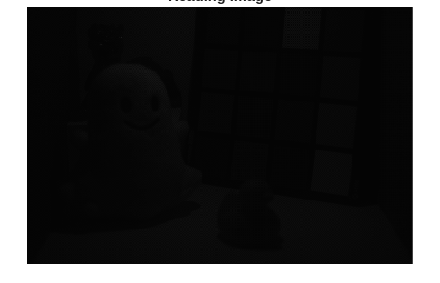

imshow(imgData)
title('Reading Image');


%Saving the image
imwrite(imgData, '02_data.png');

2.1 Reading the image information

info = imfinfo('images_tiff/IMG_0596.tiff');
bitsPerSample = info.BitsPerSample;
w = info.Width;
h = info.Height;

fprintf('Bits per sample: %s\n', num2str(bitsPerSample));

Bits per sample: 16


fprintf('Width: %s\n', num2str(w));

Width: 6024


fprintf('Height: %s\n', num2str(h));

Height: 4022


img_d = double(imgData);
%figure;
%imshow(img_d);
%title('Doble Image');

%Saving the image
imwrite(img_d, '02_double.png');

2.2 Linearization

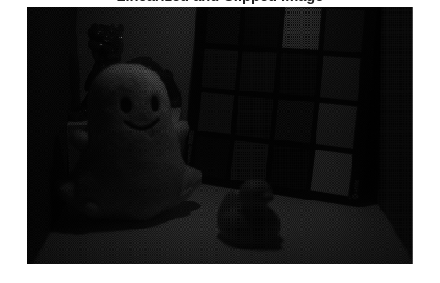

dark_noise = 1023;  % Dark noise threshold
saturation = 15600; % Saturation threshold

% Assuming 'img_d' is your input image (raw Bayer-filtered or any other)
I_linear = (img_d - dark_noise) / (saturation - dark_noise);  % Linearize the image

% Manually clip values outside the [0, 1] range
I_linear_clipped = max(min(I_linear, 1), 0);  % Clip values between 0 and 1

% Display the resulting image
figure;
imshow(I_linear_clipped);
title('Linearized and Clipped Image');


%Saving the image
imwrite(I_linear_clipped, '02_linearized.png');


**3 Demosaicing**

i) nearest neighbor 

corner_2x2 = I_linear_clipped(1:2,1:2);

    0.0130    0.0327
    0.0348    0.0201



blue_channel =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

green_channel =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0   

red_channel =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

disp(corner_2x2)

% Separate the color channels based on the Bayer pattern
% RGGB pattern

% Extract the Blue, Green, and Red channels for RGGB Bayer pattern

img_linear = I_linear_clipped;
[height, width] = size(img_linear);  % Get the dimensions of the image

% Separate the color channels based on the RGGB Bayer pattern
red_channel = zeros(height,width);
red_channel(1:2:end, 1:2:end) = img_linear(1:2:end, 1:2:end);  % Red: odd rows, odd columns
green_channel = zeros(height,width);
green_channel(1:2:end, 2:2:end) = img_linear(1:2:end, 2:2:end); % Green: even rows, odd columns
green_channel(2:2:end, 1:2:end) = img_linear(2:2:end, 1:2:end); % Green: odd rows, even columns
blue_channel = zeros(height,width);
blue_channel(2:2:end, 2:2:end) = img_linear(2:2:end, 2:2:end);   % Blue: even rows, even columns


%% 1. Fill Red Channel (Known at 1,1)
% Copy the value at (1,1) to the rest of the 2x2 block
red_full = red_channel;
red_full(1:2:end, 2:2:end) = red_full(1:2:end, 1:2:end); % Copy Right
red_full(2:2:end, 1:2:end) = red_full(1:2:end, 1:2:end); % Copy Down
red_full(2:2:end, 2:2:end) = red_full(1:2:end, 1:2:end); % Copy Diagonal

%% 2. Fill Blue Channel (Known at 2,2)
% Copy the value at (2,2) to the rest of the 2x2 block
blue_full = blue_channel;
blue_full(1:2:end, 1:2:end) = blue_full(2:2:end, 2:2:end); % Copy Diagonal Up
blue_full(1:2:end, 2:2:end) = blue_full(2:2:end, 2:2:end); % Copy Up
blue_full(2:2:end, 1:2:end) = blue_full(2:2:end, 2:2:end); % Copy Left

%% 3. Fill Green Channel (Known at 1,2 and 2,1)
% Since we have two greens, we just fill the missing spots with the nearest one
green_full = green_channel;
green_full(1:2:end, 1:2:end) = green_full(1:2:end, 2:2:end); % Top-left gets Top-right
green_full(2:2:end, 2:2:end) = green_full(2:2:end, 1:2:end); % Bottom-right gets Bottom-left



img_rgbNN = cat(3,red_full,green_full,blue_full);
% Display the RGB image
%figure;
imshow(img_rgbNN);
title('Demosaiced RGB Image / first way');
%Saving the image
imwrite(img_rgbNN, '03_NN_interpolation.png');


ii) bilinear interpolation 

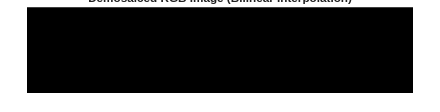

red_full_bil   = red_channel;

green_full_bil = green_channel;
blue_full_bil  = blue_channel;


%Red
cols = 2:2:width-1;
rows = 2:2:height-1;
red_full_bil(1:2:end, cols) = ...
    ( red_channel(1:2:end, cols-1) + red_channel(1:2:end, cols+1) ) / 2;
red_full_bil(rows, 1:2:end) = ...
    ( red_channel(rows-1, 1:2:end) + red_channel(rows+1, 1:2:end) ) / 2;

Error using ginput (line 84)
Interrupted by figure deletion

red_full_bil(rows, cols) = ...
    ( red_channel(rows-1, cols-1) + red_channel(rows-1, cols+1) + ...
      red_channel(rows+1, cols-1) + red_channel(rows+1, cols+1) ) / 4;


red_full_bil(end,:) = red_full_bil(end-1,:);
red_full_bil(:,end) = red_full_bil(:,end-1);

%Blue
cols = 3:2:width-1;
rows = 3:2:height-1;
blue_full_bil(2:2:end, cols) = ...
    ( blue_channel(2:2:end, cols-1) + blue_channel(2:2:end, cols+1) ) / 2;
blue_full_bil(rows, 2:2:end) = ...
    ( blue_channel(rows-1, 2:2:end) + blue_channel(rows+1, 2:2:end) ) / 2;
blue_full_bil(rows, cols) = ...
    ( blue_channel(rows-1, cols-1) + blue_channel(rows-1, cols+1) + ...
      blue_channel(rows+1, cols-1) + blue_channel(rows+1, cols+1) ) / 4;

blue_full_bil(1,:) = blue_full_bil(2,:);
blue_full_bil(:,1) = blue_full_bil(:,2);

%Green
rows = 3:2:height-1;  
cols = 3:2:width-1;   
green_full_bil(rows-2, cols-2) = ...
    ( green_channel(rows-1, cols) + ...   
      green_channel(rows, cols-1) + ...   
      green_channel(rows-2, cols-1) + ... 
      green_channel(rows-1, cols-2) ) / 4;

green_full_bil(rows-1, cols-1) = ...
    ( green_channel(rows-1, cols) + ...   
      green_channel(rows, cols-1) + ...   
      green_channel(rows-2, cols-1) + ... 
      green_channel(rows-1, cols-2) ) / 4;
 

img_rgbBL = cat(3, red_full_bil, green_full_bil, blue_full_bil);

%figure;
imshow(img_rgbBL);
title('Demosaiced RGB Image / Bilinear (RGGB)');
imwrite(img_rgbBL, '04_Bilinear_RGGB.png');


**4 White balancing**

i)  Picking the point

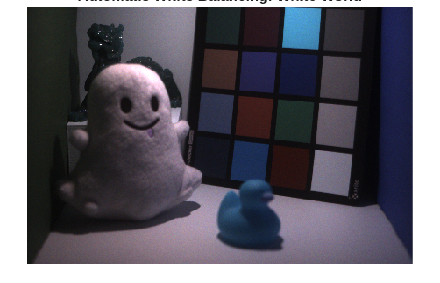

% Display the image so we can pick a point
imshow(imgRGB * 5); % Scale for visibility if raw is dark
title('Click on a neutral gray or white object');

% Using ginput to get the coordinates of our choice
[x, y] = ginput(1); 
x = round(x); 

y = round(y);

% Extracting the R, G, B values at that point
R_ref = imgRGB(y, x, 1);
G_ref = imgRGB(y, x, 2);
B_ref = imgRGB(y, x, 3);

% Compute the average intensity of the reference point
avg_ref = (R_ref + G_ref + B_ref) / 3;

% Compute the scale factors
SR = avg_ref / R_ref;
SG = avg_ref / G_ref;
SB = avg_ref / B_ref;

% Applying the scale factors to all pixels
rgb_wb = zeros(size(imgRGB));
rgb_wb(:,:,1) = imgRGB(:,:,1) * SR; % Red channel
rgb_wb(:,:,2) = imgRGB(:,:,2) * SG; % Green channel
rgb_wb(:,:,3) = imgRGB(:,:,3) * SB; % Blue channel

% Final display (clipping values above 1.0 to avoid artifacts)
%TODO: check this factor because I put in order to see the image
imshow(min(rgb_wb * 5, 1.0)); 
%imshow(rgb_wb); 
title('Manually White Balanced Image');


ii) the white world white balancing

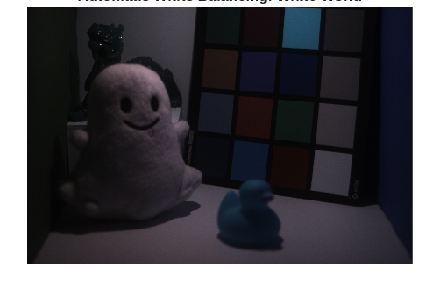

% Find the maximum value in each channel
R_max = max(img_rgbNN(:,:,1), [], 'all');
G_max = max(img_rgbNN(:,:,2), [], 'all');
B_max = max(img_rgbNN(:,:,3), [], 'all');


% Calculate the average of the maximums
avg_max = (R_max + G_max + B_max) / 3;

% Compute the scale factors based on the assignment formula
SR_w = avg_max / R_max;
SG_w = avg_max / G_max;
SB_w = avg_max / B_max;

% Create the corrected image
rgb_white_world = img_rgbNN;
rgb_white_world(:,:,1) = img_rgbNN(:,:,1) * SR_w;
rgb_white_world(:,:,2) = img_rgbNN(:,:,2) * SG_w;
rgb_white_world(:,:,3) = img_rgbNN(:,:,3) * SB_w;

% Display the result
imshow(min(rgb_white_world * 5, 1.0));
title('Automatic White Balancing: White World');


iii)   gray world white balancing

% Calculate the average (mean) value for each channel
R_avg = mean(img_rgbNN(:,:,1), 'all');
G_avg = mean(img_rgbNN(:,:,2), 'all');
B_avg = mean(img_rgbNN(:,:,3), 'all');

% Compute the scale factors based on the assignment formula
%SR_g = avg_max / R_max;
%SG_g = avg_max / G_max;
%SB_g = avg_max / B_max;

avg_max = ((R_max/2) + (G_max/2) + (B_max/2)) / 3;

SR_w = avg_max / (R_max/2);
SG_w = avg_max / (G_max/2);
SB_w = avg_max / (B_max/2);

%SR_g = SR_w / 2;
%SG_g = SG_w / 2;
%SB_g = SB_g / 2;

% Create the corrected image
rgb_gray_world = img_rgbNN;
rgb_gray_world(:,:,1) = img_rgbNN(:,:,1) * SR_g;
rgb_gray_world(:,:,2) = img_rgbNN(:,:,2) * SG_g;
rgb_gray_world(:,:,3) = img_rgbNN(:,:,3) * SB_g;

% Display the result
imshow(min(rgb_gray_world  * 5, 1.0));
title('Automatic White Balancing: White World');



**5 Denoising**

i) mean filtering

%TODO: complete / 1 point each
%----------------------------------------------------
%-5 Denoising
%----------------------------------------------------
%- i) mean filtering
%----------------------------------------------------





ii) median filtering

%TODO: complete / 1 point each
%----------------------------------------------------
%-5 Denoising
%----------------------------------------------------
%- ii) median filtering
%----------------------------------------------------

iii) Gaussian filtering.

%TODO: complete / 1 point each
%----------------------------------------------------
%-5 Denoising
%----------------------------------------------------
%- iii) Gaussian filtering.
%----------------------------------------------------

**6 Color balance**

img_hsv = rgb2hsv(img_rgbBL);

boost_factor = 1.5; 
img_hsv(:,:,2) = img_hsv(:,:,2) * boost_factor;
img_hsv(:,:,2) = min(img_hsv(:,:,2), 1); % clamp to 1

img_cb = hsv2rgb(img_hsv);
imshow(img_cb);
title('Color Balance');
imwrite(img_cb, 'color_balance.png');

**7 Tone reproduction**

gamma = 2.4;      
alpha = 0;      

img_adjusted = img_cb * 2^alpha;

img_tone = zeros(size(img_adjusted));

for c = 1:3
    C = img_adjusted(:,:,c);
    
    mask = C <= 0.0031308;
    % C <= 0.0031308 case
    C_nonlin = zeros(size(C));
    C_nonlin(mask) = 12.92 * C(mask);
    
    % C > 0.0031308 case
    C_nonlin(~mask) = (1 + 0.055) * C(~mask).^(1/gamma) - 0.055;
    
    img_tone(:,:,c) = C_nonlin;
end

img_tone = min(max(img_tone, 0), 1); % clamp to 1

imshow(img_tone);
title('Tone reproduction');
imwrite(img_tone, 'final_tone.png');


**8 Compression**

imwrite(img_tone, 'final.png');
imwrite(img_tone, 'final.jpg', 'Quality', 95);


%info
info_png = dir('final.png');
info_jpg = dir('final.jpg');

size_png = info_png.bytes;
size_jpg = info_jpg.bytes;

compression_ratio = size_png / size_jpg;

fprintf('PNG size: %d bytes\n', size_png);
fprintf('JPEG size: %d bytes\n', size_jpg);
fprintf('Compression ratio (PNG/JPEG): %.2f\n', compression_ratio);